# EXAMEN- Olaia Perez 

**EJERCICIO 1-FILTRO FIR**

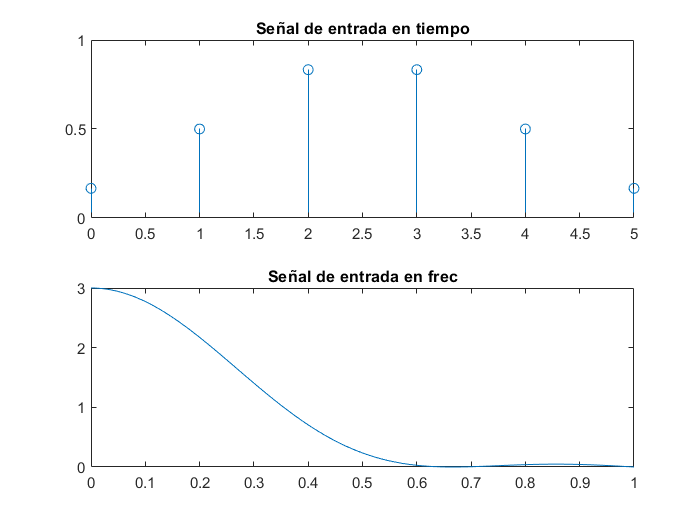

N=6;
n=linspace(0,N-1,N);
w=linspace(0,pi,301);
x=triang(N)';
X=DTFT(x,n,w);
%a
subplot(211);stem(n,x);title('Señal de entrada en tiempo')
subplot(212);plot(w/pi,abs(X));title('Señal de entrada en frec')

figure;

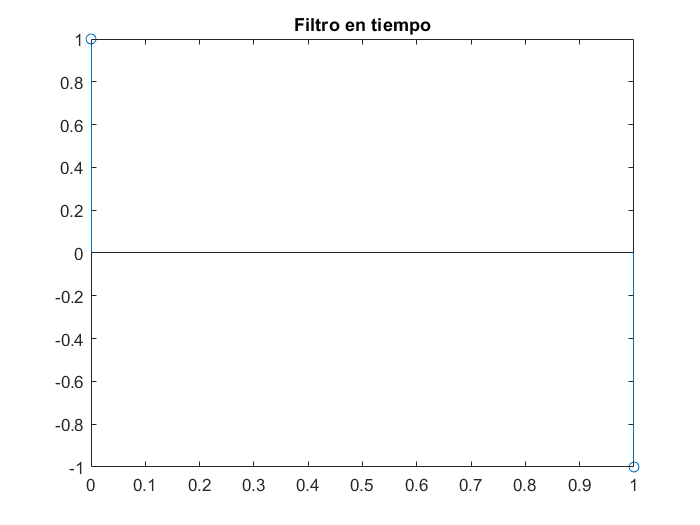

%b
%y=x[n]-x[n-1]
hd=[1,-1];
Nh=length(hd);
k=linspace(0,Nh-1,Nh);
stem(k,real(hd));title('Filtro en tiempo')

figure;

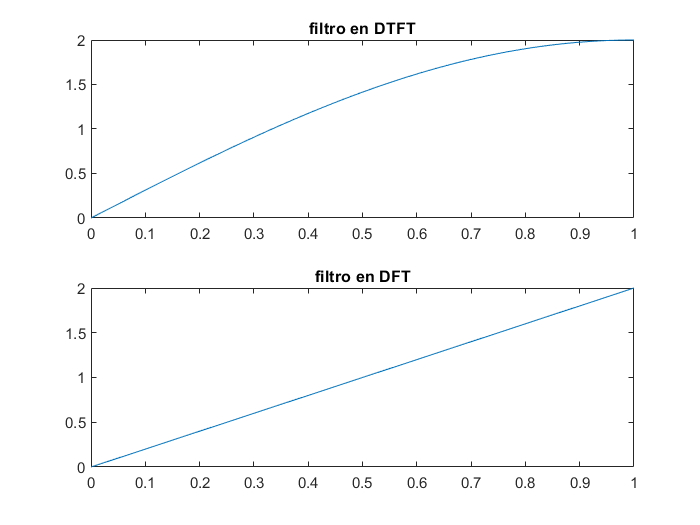

%c
kf=k*2*pi/Nh;
H=fft(hd);
hdtft=DTFT(hd,k,w);
subplot(211);plot(w/pi,abs(hdtft));title('filtro en DTFT')
subplot(212);plot(kf/pi,abs(H));title('filtro en DFT')

figure;
%se trata de un filtro paso alto

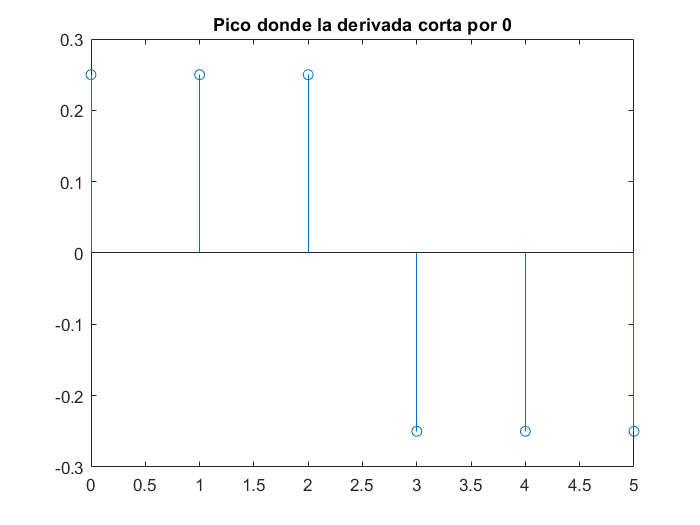

%d
nf=linspace(-Nh+1,N-1,N+Nh-1);
xf=triang(N+Nh-1)';
y=ifft(fft(xf).*fft(hd,N+Nh-1));
yf=y(Nh:N+Nh-1);
Yf=DTFT(yf,n,w);
stem(n,real(yf));title('Pico donde la derivada corta por 0') %efectivamente es 0 para 2.5

**EJERCICIO 2- FILTRO IIR**

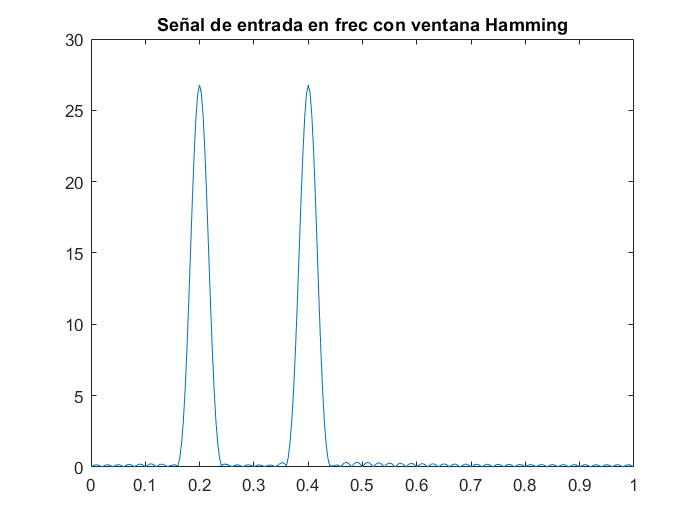

N2=100;
n2=linspace(0,N2-1,N2);
x2=cos(0.2*pi*n2)+cos(0.4*pi*n2);
w=linspace(0,pi,301);
%a
X2w=DTFT(x2.*hamming(N2)',n2,w); %aplico la ventana Hamming sobre la señal de entrada
plot(w/pi,abs(X2w)); title('Señal de entrada en frec con ventana Hamming') 

%compruebo que efectivamente, los valores máximos se dan en 0.2 y 0.4

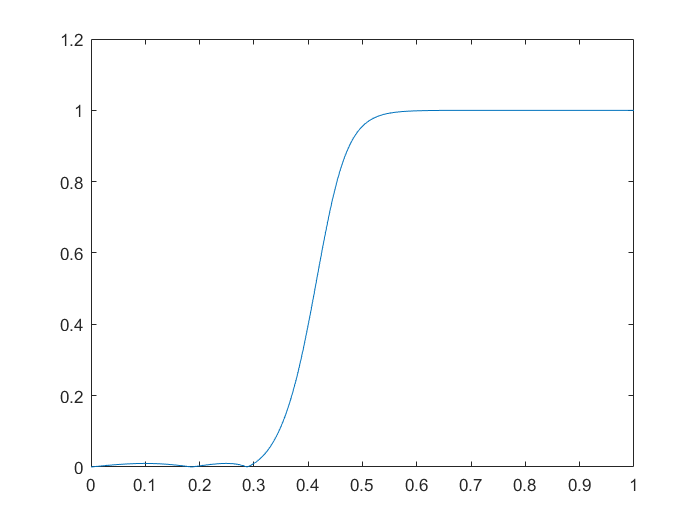

%b
%Para ello, escojo un filtro Chebychev tipo II
[b,a]=cheby2(5,40,0.30,'high');
hc=filter(b,a,delta(n2,0));
Hc=DTFT(hc,n2,w);
plot(w/pi,abs(Hc)) 

%tras haber hecho varias pruebas, para dejar sólo la componente de alta frec
% he escogido: N=5, As=40 y Wsn=0.30 (paso alto)

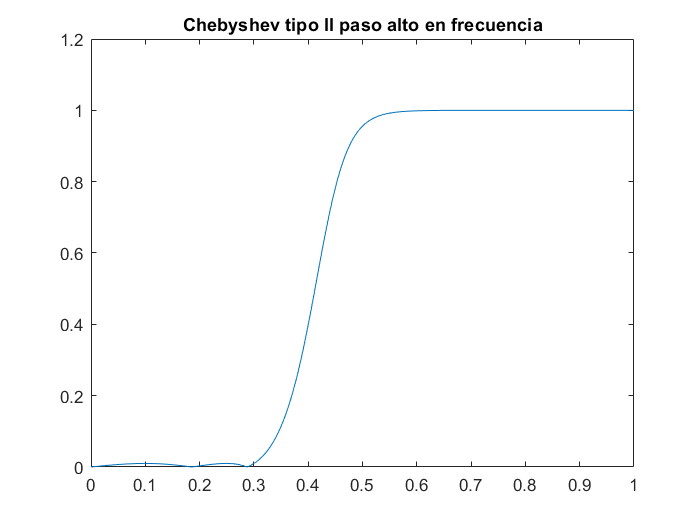

%c
plot(w/pi,abs(Hc)); title('Chebyshev tipo II paso alto en frecuencia')

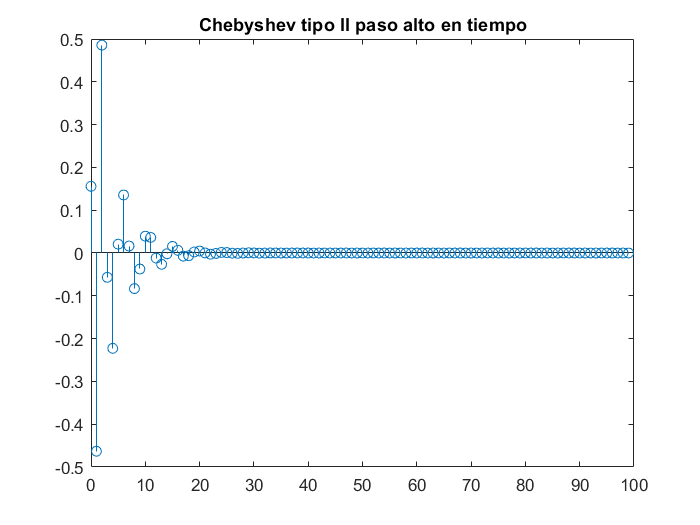

stem(n2,real(hc)); title('Chebyshev tipo II paso alto en tiempo')

%d
%max(hc) me devuelve donde se da el valor más alto del filtro: 0.4857 (corresponde con la gráfica en frecuencia)
%find(abs(hc)>max(abs(hc)/20)) busca aquellos valores mayores que el maximo/20 : 11 valores
Nc=max(find(abs(hc)>max(hc)/20)) %definitivamente el tamño del filtro será el mayor de esos 11 valores

Nc = 14

%El tamaño del filtro es 14 

%e, INVERSA TRANSFORMADA Z
[r,p,k]=residuez(b,a)

r =   -0.0570 - 0.3240i
  -0.0570 + 0.3240i
  -1.3387 - 0.4722i
  -1.3387 + 0.4722i
  -3.6386 + 0.0000i


p =    0.1689 + 0.7629i
   0.1689 - 0.7629i
   0.1926 + 0.3789i
   0.1926 - 0.3789i
   0.2145 + 0.0000i


k = 6.5858

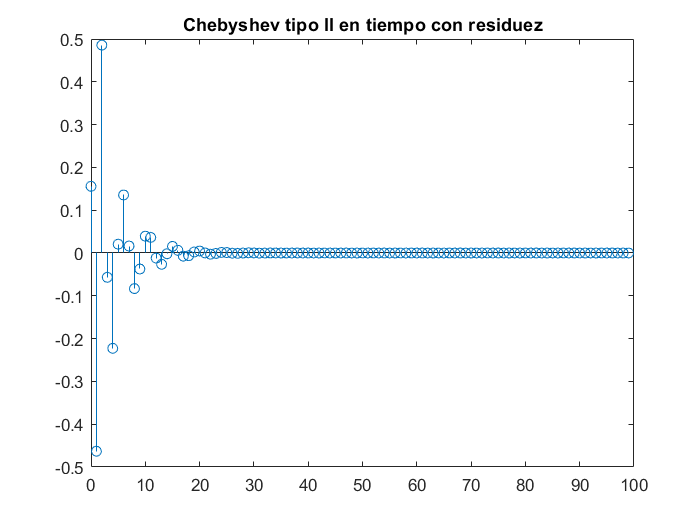

% Dado que no hay dos polos en el mismo sitio, considero grado 1 
h=sum(r.*(p.^n2).*escalon(n2,0))+k.*delta(n2,0); %abreviado
stem(n2,real(h)); title('Chebyshev tipo II en tiempo con residuez')

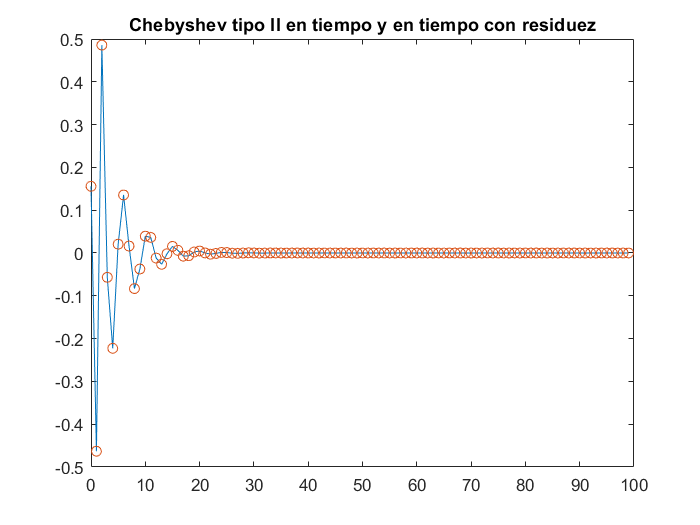

plot(n2,real(h),n2,real(hc),'o'); title('Chebyshev tipo II en tiempo y en tiempo con residuez') 

%represento Chebyshev en tiempo y en tiempo con residuez para ver mejor que coincidan

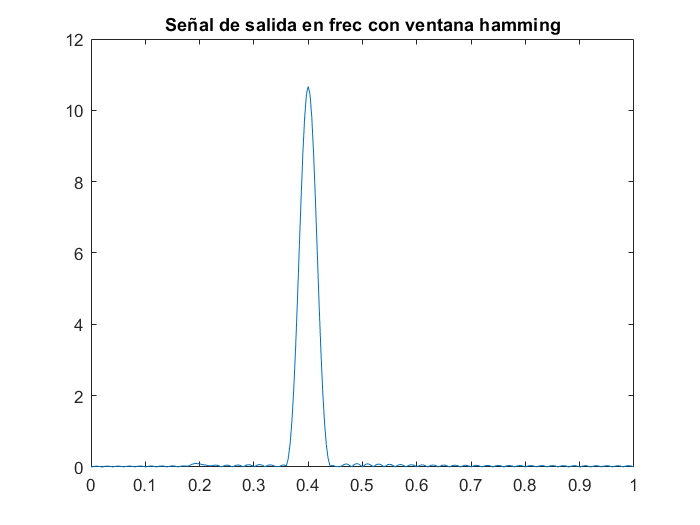

%f
nc=linspace(-Nc+1,N2-1,N2+Nc-1);
xc=cos(0.2*pi*nc)+cos(0.4*pi*nc);
yci=filter(b,a,xc);
yc=yci(Nc:N2+Nc-1);
Y2cw=DTFT(yc.*hamming(N2)',n2,w);
plot(w/pi,abs(Y2cw)); title('Señal de salida en frec con ventana hamming')

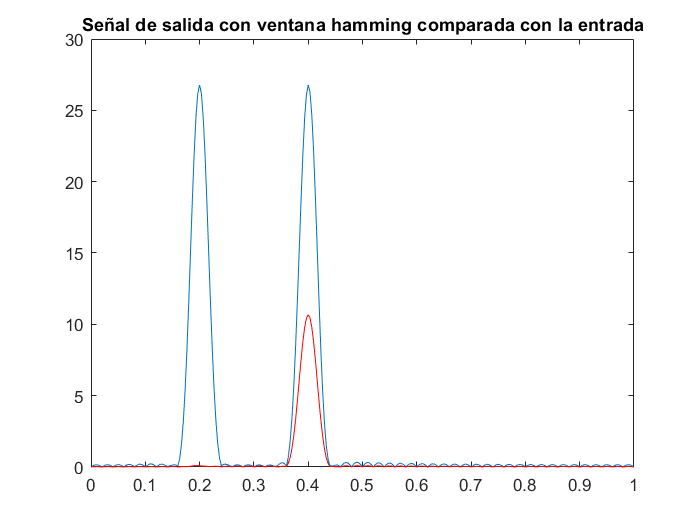

plot(w/pi,abs(X2w),w/pi,abs(Y2cw),'r');title('Señal de salida con ventana hamming comparada con la entrada')

%siendo la señal de entrada la azul y la de salida la roja, FILTRO FUNCIONA
